%% (L/D)max estimation of similar UAVs

%% AUTHOR = MONISHA VIJAYAN (AE25M037) & ABHIJEET MANGELA (AE25M034)
% UAV Names
e=[];
Name = {
    'Yangda Mapird Plus'
    'Yangda FW-250'
    'Avy Aera'
    'Foxtech Baby Shark 260'
    'Foxtech AYK-250'
    'FlyDragon FLY-2100'
    'Black Swift S2'
    'Foxtech Nimbus'
};
% MTOW (kg)
MTOW = [ ...
     11.5 12.0 12.0 13.0  15.0 ...
     7.0 9.5  6.0 ];
% Wing span(m)
b = [...
     2.43 2.5 2.4 2.5 2.5 ...
     2.1 3 1.8];
% Wing area (m^2)
Area = [ ...
     0.65  0.52 0.96 0.50 0.50 ...
     0.52 0.70  0.38 ];
% Aspect ratio
AR = [ ...
     9.08  12.02 6.00 12.50 12.50 ...
     8.48 12.86 8.53 ];
% Cruising Altitude (m)
hcruise = [ ...
     3500 3500 3100 3000 2000 ...
     500 4250 1500 ];
% Cruising speed (m/s)
vcruise = [ ...
     19.44 23.33 26.39 22 ...
    25.00 18.5 18.06 20];
%Swet/Sref 
sratio =[...
    3.7 3.4 2.20 2.3 2.20...
     3.7 2.3  3.7];
swet=[];
ARwet=[];
for i = 1:length(sratio)
    swt=sratio(i)*Area(i);
    swet(end+1)=swt;
    ARwt=(b(i)^2)/swet(i);
    ARwet(end+1)=ARwt;
end


%Planform type
Planform = {
    'Rectangular'
    'Tapered'
    'Tapered'
    'Tapered'
    'Tapered'
    'Rectangular'
    'Rectangular'
    'Rectangular'
};
  

% Taper Ratio
TR=[...
    1, 0.141, 0.287, 0.119, 0.149, 1, 1, 1 ...
];
%------------------------------------------------------------------------
%Oswald Efficiency Factor
for i = 1:length(MTOW)
    if strcmp(Planform{i},'Rectangular')
        eu(i) = 1.78*(1 - 0.045*AR(i)^0.68) - 0.64;

    elseif strcmp(Planform{i},'Tapered')
        d(i) = (1-TR(i))/(2*(1+TR(i)));
        eu(i) = 1/(1+d(i));
    end
    e(end+1)=eu(i);
end
e = max(e, 0.7);
e = min(e, 1.0);
%disp(e)
%------------------------------------------------------------------------
%ISA Parameters
h = hcruise;
rho = NaN(size(h));    
T0 = 288.15;             
P0 = 101325;              
rho0 = 1.225;             
L = 0.0065;               
R = 287.05;               
g = 9.80665;              
%------------------------------------------------------------------------
%Density Calculation
for i = 1:length(h)
    if ~isnan(h(i))
        T = T0 - L*h(i);
        rho(i) = rho0*(T/T0)^(g/(R*L) - 1);
    end
end

%disp(rho)
%------------------------------------------------------------------------
%L/D max calculation
L_Dm = [];

for i=1:length(MTOW)
    Cl=(2*MTOW(i)*9.81)/(rho(i)*Area(i)*(vcruise(i)^2));
    L_D=(pi*e(i)*AR(i))/(2*Cl);
    L_Dm(end+1)=L_D;
end
%------------------------------------------------------------------------
%for our UAV
sratio1=3.6;
Sref=0.413;
swet=sratio1*Sref;
ARwsk =4/swet;
disp(sqrt(ARwsk))

    1.6402



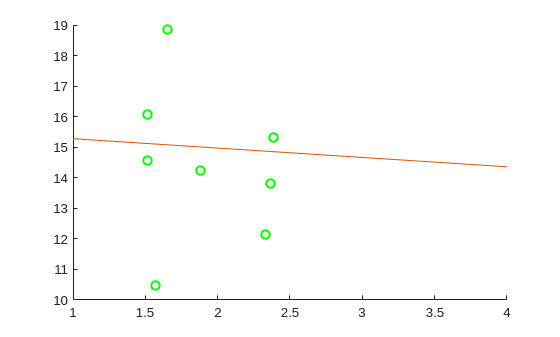

%------------------------------------------------------------------------
%[AR_sorted, idx] = sort(sqrt(ARwet));
%L_dm_sorted = L_Dm(idx);
x= linspace(1,4,100);
fit =polyfit(ARwet,L_Dm,1);
y=polyval(fit,x);
figure
scatter(sqrt(ARwet),L_Dm,40,"green","o",'LineWidth',1.5)
hold on
plot(x,y)

Table = table(Name(:), MTOW(:), vcruise(:), hcruise(:), ARwet(:), L_Dm(:), ...
              'VariableNames', {'Name','MTOW (kg)','cruise velocity (m/s)', 'Cruising Height (m)', 'Wetted Aspect Ratio', 'L_D_max'})

Table = 8×6 table
               Name               MTOW (kg)    cruise velocity (m/s)    Cruising Height (m)    Wetted Aspect Ratio    L_D_max
    __________________________    _________    _____________________    ___________________    ___________________    _______

    {'Yangda Mapird Plus'    }      11.5               19.44                   3500                  2.4553           10.468 
    {'Yangda FW-250'         }        12               23.33                   3500                  3.5351           14.235 
    {'Avy Aera'              }        12               26.39                   3100                  2.7273           18.858 
    {'Foxtech Baby Shark 260'}        13                  22                   3000                  5.4348           12.153 
    {'Foxtech AYK-250'       }        15                  25                   2000                  5.6818           15.314 
    {'FlyDragon FLY-2100'    }         7                18.5                    500                

writetable(Table, 'Dataset_2.xlsx')

our_L_D_max = polyval(fit,sqrt(ARwsk))

our_L_D_max = 15.0828

ARwsk

ARwsk = 2.6903

sqrt(ARwsk)

ans = 1.6402

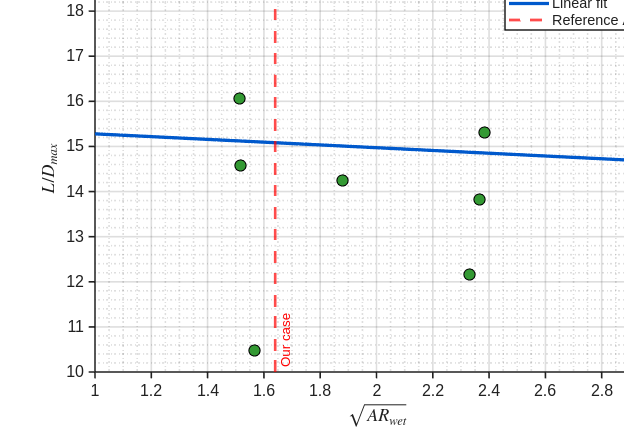

x = linspace(1,3,200);

fit = polyfit(ARwet, L_Dm, 1);
y   = polyval(fit, x);

figure('Color','w','Position',[200 200 800 550])   % white bg + larger figure

% ---- Scatter ----
scatter(sqrt(ARwet), L_Dm, 70, ...
        'filled', ...
        'MarkerFaceColor',[0.2 0.6 0.2], ...
        'MarkerEdgeColor','k', ...
        'LineWidth',0.8)
hold on

% ---- Fit line ----
plot(x, y, ...
     'LineWidth', 2.5, ...
     'Color',[0 0.35 0.8])

% ---- Vertical line ----
xline(sqrt(ARwsk), '--r', ...
      'LineWidth', 2, ...
      'Label','Our case', ...
      'LabelVerticalAlignment','bottom')

% ---- Labels ----
xlabel('$\sqrt{AR_{wet}}$','Interpreter','latex','FontSize',14)
ylabel('$L/D_{max}$','Interpreter','latex','FontSize',14)
title('Lift-to-Drag Ratio vs Aspect Ratio','FontSize',15)

% ---- Grid & styling ----
grid on
grid minor
box on

set(gca, ...
    'FontSize',12, ...
    'LineWidth',1.2, ...
    'TickDir','out')

legend({'Data','Linear fit','Reference AR'}, ...
        'Location','northeast')

% cruise
AR=9.686

AR = 9.6860

MTOW=68.516; %MTOW=57.94 AFTER PAYLOAD
e=1.78*(1-0.045*AR^0.68)-0.64 %for rectangular wing

e = 0.7648

rho=1.225; % @ cruising altitude = 200m
b=2;
s=(b^2)/AR

s = 0.4130

vcr=22;
Cl=(2*MTOW)/(rho*vcr^2*s);
k=1/(pi*AR*e);
v0=30; 
L_D_max = our_L_D_max

L_D_max = 15.0828

gamma = 8;
Lift_cruise = MTOW

Lift_cruise = 68.5160

Drag_cruise = Lift_cruise/L_D_max

Drag_cruise = 4.5427

thrust_required_cruise = Drag_cruise

thrust_required_cruise = 4.5427

C_L_cruise = @(v) Lift_cruise/(0.5*rho*s*v^2)

C_L_cruise = function_handle with value:
    @(v)Lift_cruise/(0.5*rho*s*v^2)


C_d_i_cruise_func = @(v) C_L_cruise(v)^2/(pi*e*AR);
Drag_function_cruise = @(v)(0.5*rho*s*v^2*(2*C_d_i_cruise_func(v))) - Drag_cruise;
optimal_velocity_cruise = fsolve(Drag_function_cruise,v0)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.



optimal_velocity_cruise = 18.7373

Power_required_cruise = thrust_required_cruise*optimal_velocity_cruise

Power_required_cruise = 85.1173

T_W_cruise=thrust_required_cruise/MTOW

T_W_cruise = 0.0663

P_W_cruse = Power_required_cruise/MTOW

P_W_cruse = 1.2423

CDo = C_d_i_cruise_func(optimal_velocity_cruise);

% climb
gamma = 5

gamma = 5

Lift = MTOW*cosd(gamma)

Lift = 68.2553

Drag = 2*Lift/(sqrt(3)*L_D_max)

Drag = 5.2255

thrust_required_climb = Drag + MTOW*sind(gamma)

thrust_required_climb = 11.1970

C_L_climb = @(v) Lift/(0.5*rho*s*v^2)

C_L_climb = function_handle with value:
    @(v)Lift/(0.5*rho*s*v^2)


C_d_i_climb_func = @(v) C_L_climb(v)^2/(pi*e*AR);
Drag_function = @(v)(0.5*rho*s*v^2*(CDo + C_d_i_climb_func(v))) - Drag;
optimal_velocity_climb = fsolve(Drag_function,v0)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.



optimal_velocity_climb = 24.6127

Power_required_climb = thrust_required_climb*optimal_velocity_climb

Power_required_climb = 275.5890

T_W_climb=thrust_required_climb/MTOW

T_W_climb = 0.1634

P_W_climb = Power_required_climb/MTOW

P_W_climb = 4.0223

% descent
gamma =-8

gamma = -8

Lift = MTOW*cosd(gamma)

Lift = 67.8492

Drag = 2*Lift/(sqrt(3)*L_D_max)

Drag = 5.1944

thrust_required_descent = Drag + MTOW*sind(gamma)

thrust_required_descent = -4.3412

C_L_descent = @(v) Lift/(0.5*rho*s*v^2)

C_L_descent = function_handle with value:
    @(v)Lift/(0.5*rho*s*v^2)


C_d_i_descent_func = @(v) C_L_descent(v)^2/(pi*e*AR);
Drag_function = @(v)(0.5*rho*s*v^2*(CDo + C_d_i_descent_func(v))) - Drag;
optimal_velocity_descent = fsolve(Drag_function,v0)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.



optimal_velocity_descent = 24.5394

Power_required_descent = thrust_required_descent*optimal_velocity_descent

Power_required_descent = -106.5308

T_W_descent=thrust_required_descent/MTOW

T_W_descent = -0.0634

P_W_climb = Power_required_descent/MTOW

P_W_climb = -1.5548

% loiter

gamma = 0

gamma = 0

Lift = MTOW*cosd(gamma)

Lift = 68.5160

Drag = 2*Lift/(sqrt(3)*L_D_max)

Drag = 5.2454

thrust_required_loiter = Drag + MTOW*sind(gamma)

thrust_required_loiter = 5.2454

C_L_loiter = @(v) Lift/(0.5*rho*s*v^2)

C_L_loiter = function_handle with value:
    @(v)Lift/(0.5*rho*s*v^2)


C_d_i_loiter_func = @(v) C_L_loiter(v)^2/(pi*e*AR);
Drag_function = @(v)(0.5*rho*s*v^2*(CDo + C_d_i_loiter_func(v))) - Drag;
optimal_velocity_loiter= fsolve(Drag_function,v0)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.



optimal_velocity_loiter = 24.6597

Power_required_loiter = thrust_required_loiter*optimal_velocity_loiter

Power_required_loiter = 129.3502

T_W_loiter=thrust_required_loiter/MTOW

T_W_loiter = 0.0766

P_W_loiter = Power_required_loiter/MTOW

P_W_loiter = 1.8879

appox_c = b/AR

appox_c = 0.2065